# PHYS 4002 Matlab Notes

ones_matrix = ones(2);
zeros_matrix = zeros(2);

% Identity matrix
id_2x2 = eye(2,2);
% Create a vector x from 1 to 19 with only odds
x = 1:2:19;
% Linearly spaced bins. Includes both zero and pi
lazy_vector = linspace(0,pi,500);

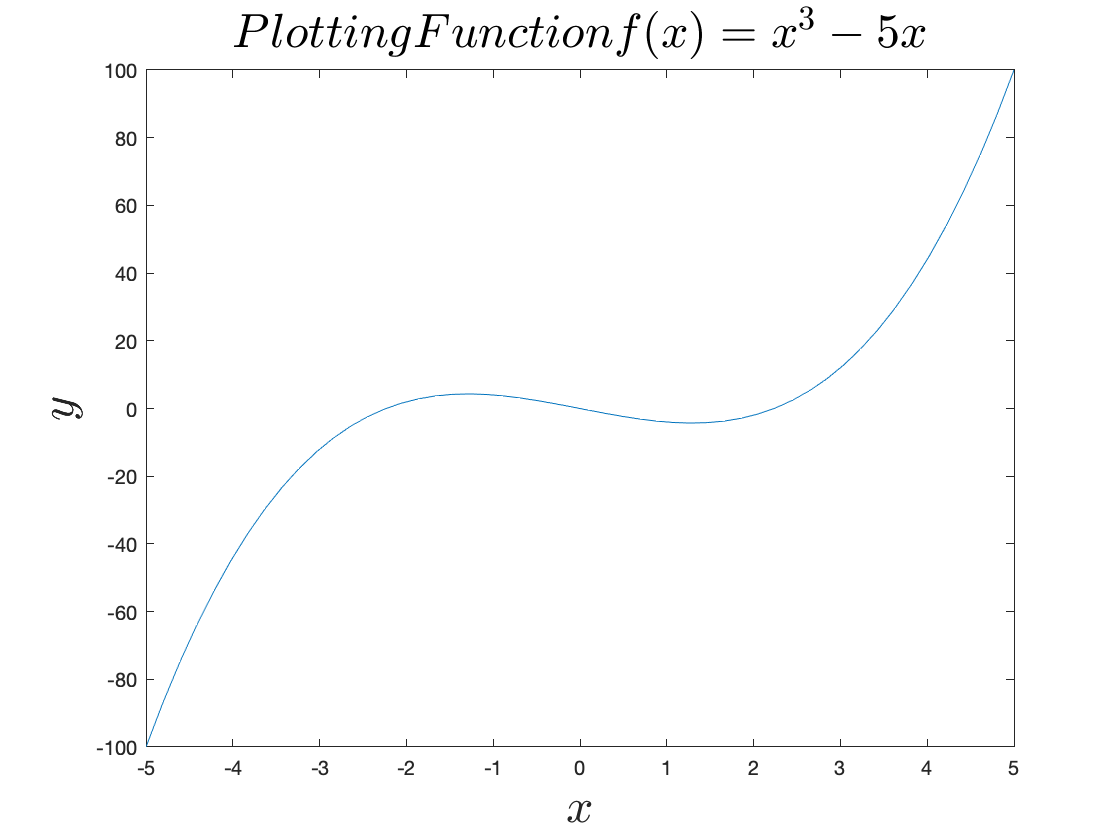

Nx = 52;
x_axis = linspace(-5,5,Nx);
y_axis = x_axis.^3 - 5.*x_axis;

plot(x_axis,y_axis)
xlabel("$x$","Fontsize",24,'Interpreter','latex')
ylabel("$y$","Fontsize",24,'Interpreter','latex')
title("$Plotting Function f(x) = x^3 - 5x$","Fontsize",24,...
    'Interpreter','latex')

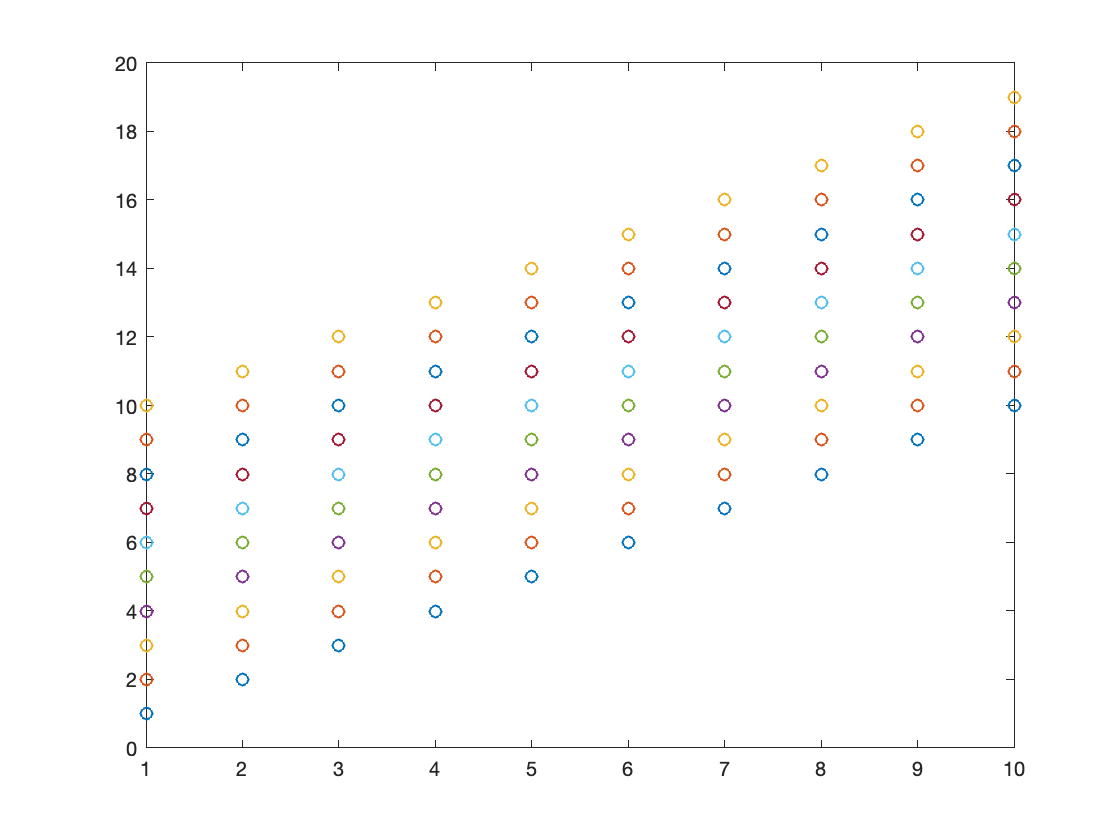


id_2x2 = eye(2,2);
A = [0 1;1 0];
kron(id_2x2,A);
kron(A,id_2x2);
M_kron = kron(ones(10,1),[1:2:20]);
M_kron = 0.5*(M_kron+M_kron');
plot(M_kron,'o')

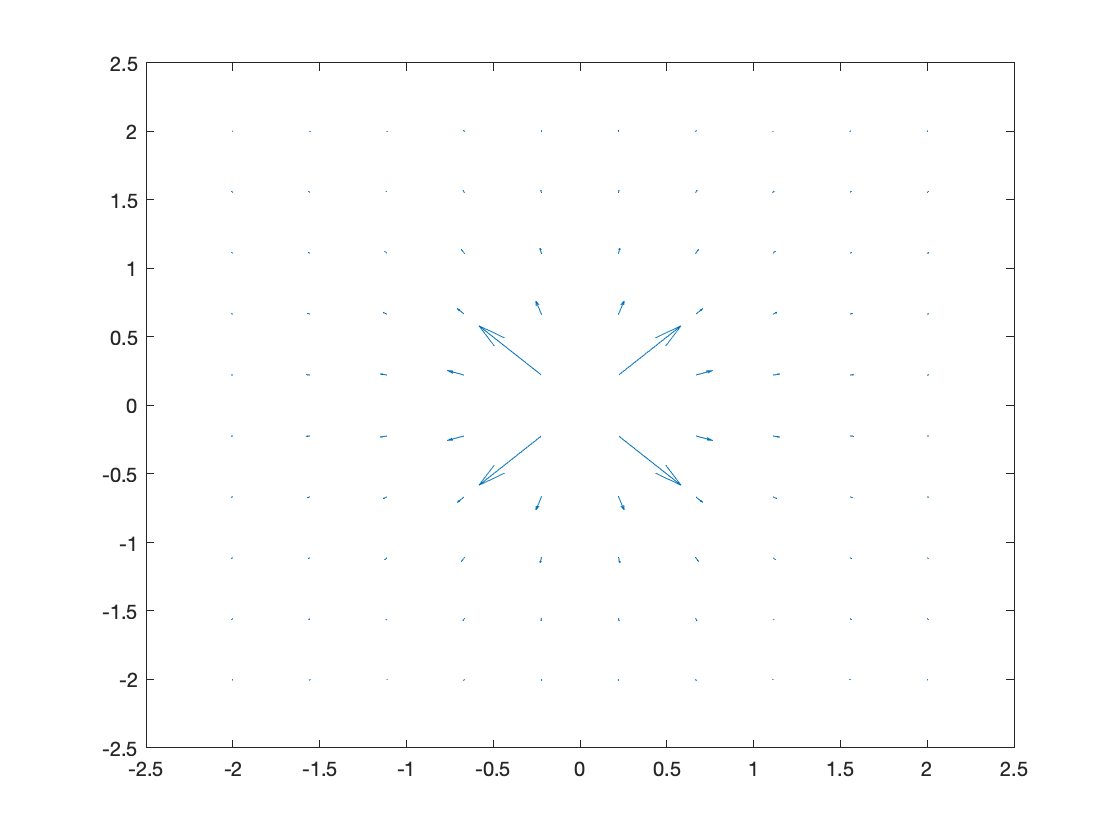

% Vector field
r0 = [0 0 0];
minB = -2;
maxB = 2;
points_to_sample = 10;
vector_range = linspace(minB, maxB, points_to_sample);
% Create a charge at the origin
[X_Axis, Y_Axis] = meshgrid(vector_range, vector_range);

Efield_x = ones(size(X_Axis));
Efield_y = ones(size(X_Axis));

for i = 1:points_to_sample
    for j = 1:points_to_sample
        location = [X_Axis(i,j) Y_Axis(i,j) 0];
        Efield = pointchargeE(location, r0);
        Efield_x(i,j) = Efield(1);
        Efield_y(i,j) = Efield(2);
    end
end

quiver(X_Axis, Y_Axis, Efield_x, Efield_y)

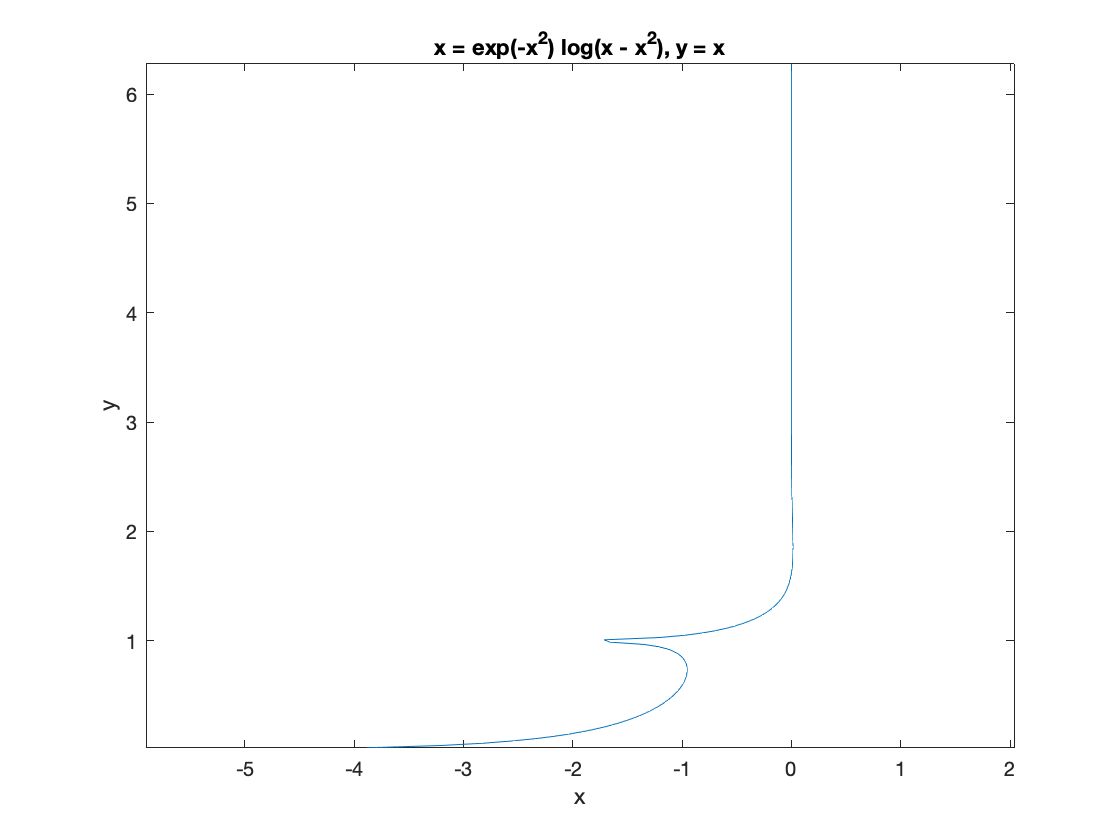

syms f(x,y);

f(x,y) = exp(- x^2 - y^2);
diff(f,x);

syms g(x);
g(x) = exp(-x^2) * log(x - x^2);
% Plotting function that takes symbolic argument
ezplot(g,x)

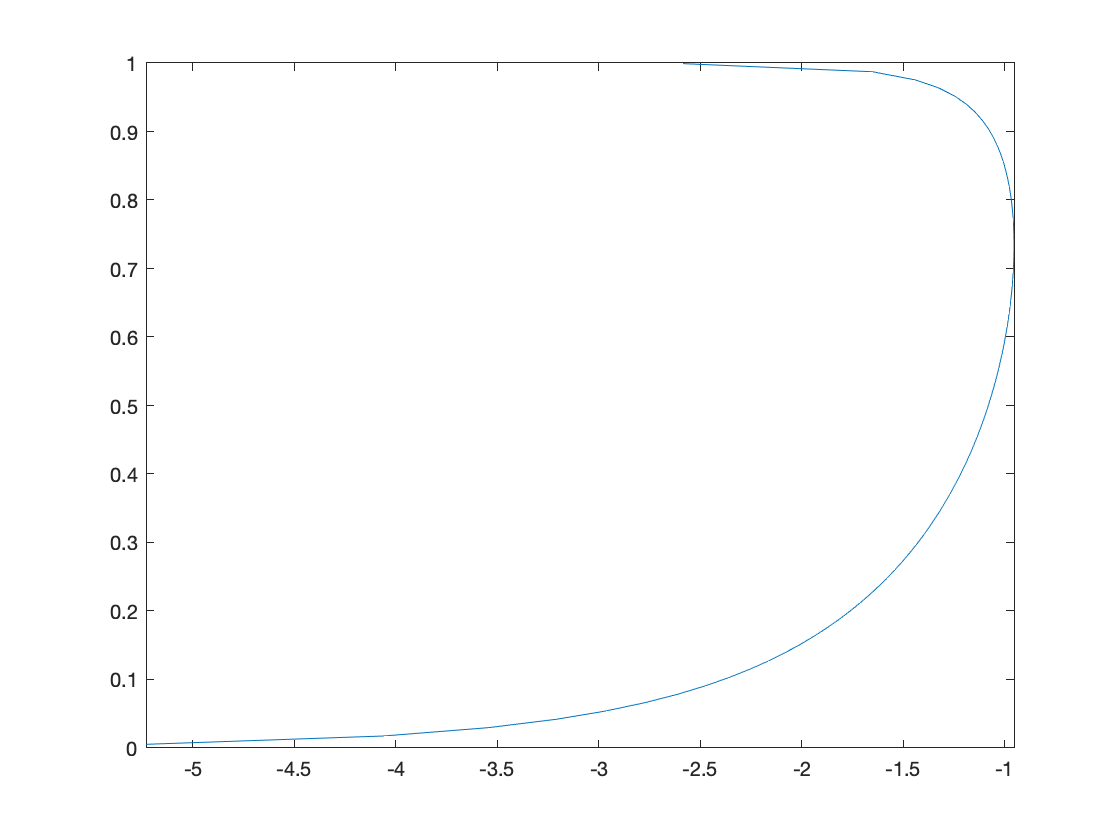

fplot(g,x,[-5,5])


% Riemann Integration
Nx = 100;
x_axis = linspace(0,1,Nx);
y_axis = exp(x_axis);

% R.sum = dx * sum( a lot of stuff )
dx = x_axis(2) - x_axis(1);
riemann_sum = dx*sum(y_axis)

riemann_sum = 1.7371